# Linear Regression

## 1. Linear regression with one variable

Implementation of linear regression with one variable to predict profits for a business based on populations from cities.

The file `data1.txt `contains the dataset for the linear regression problem. The first column is the population of a city and the second column is the profit of the business in that city. A negative value for profit indicates a loss.

### 1.1 Plotting the data

clear
data = load('data1.txt'); % load comma separated data
X = data(:, 1); y = data(:, 2);

plotData(X,y)

### 1.2 Cost function and gradient descent

#### 1.2.1 Update equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \;$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


One way to minimize cost $J(\theta)$ by adjusting parameters of model (the $\theta$ values) is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\;\;\;\;\;\left(\textrm{simultaneously}\;\textrm{update}\;\theta_{j\;} \;\textrm{for}\;\textrm{all}\;j\right)$$


#### 1.2.2 Implementation

m = length(X); % number of training examples
X = [ones(m,1),data(:,1)]; % add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500; % number of iterations
alpha = 0.01; % learning rate

#### 1.2.3 Computing the cost $\mathit{\mathbf{J}}\left(\theta \right)$

% compute and display initial cost with theta all zeros
costFunction(X, y, theta)

ans = 32.0727

This time with non-zero `theta` values as an additional test.

costFunction(X, y,[-1; 2])

ans = 54.2425

#### 1.2.4 Computing gradient descent

% run gradient descent:

% compute theta
theta = gradientDescent(X, y, theta, alpha, iterations);

% print theta to screen
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

Theta computed from gradient descent:
-3.630291,
1.166362

Computing the cost function this time with founded theta by gradient descent algorithm.

costFunction(X, y, theta)

ans = 4.4834

It can be noticed that the value of cost function decreased considerably in comparison to the calculated value by random theta as above and as a matter of fact it's the least value of the cost function.

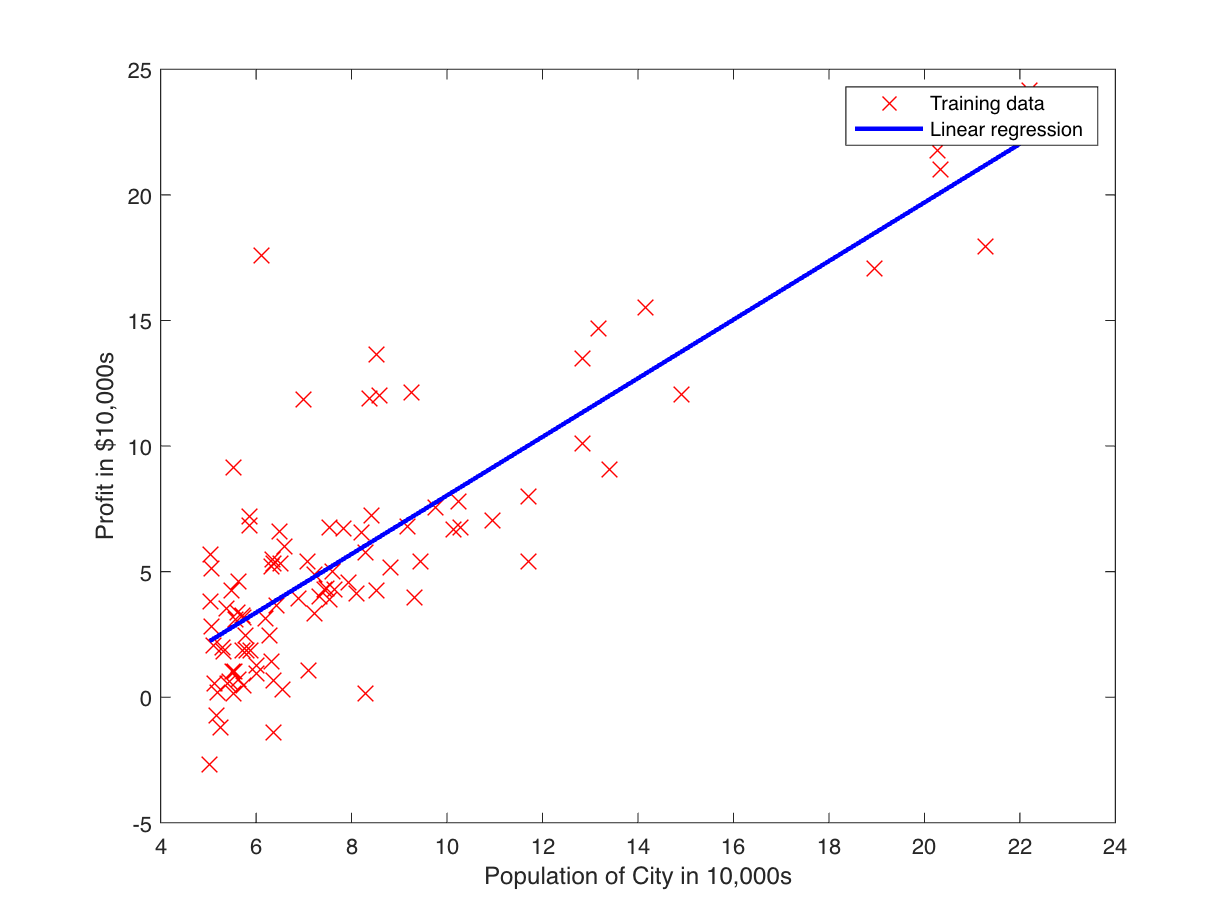

% plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta,'b','LineWidth',2)
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure

% predict values for population sizes of 35,000 and 70,000

predict1 = [1, 3.5] * theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);

For population = 35,000, we predict a profit of 4519.767868


predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

For population = 70,000, we predict a profit of 45342.450129


### 1.3 Visualizing $J(\theta)$

% visualizing J(theta_0, theta_1):

% grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = costFunction(X, y, t);
    end
end

J_vals = J_vals';

% surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

% contour plot
figure;
% plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

## 2. Regularized linear regression with one variable

Implementation of regularized linear regression with one variable for the same example as above to predict profits for a business based on populations from cities.

### 2.1 Plotting the data

clear
data = load('Data1.txt'); % load comma separated data
X = data(:, 1); y = data(:, 2);

plotData(X,y)

### 2.2 **Cost function and gradient descent**

The objective of regularized linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 +\lambda \sum_{j=1}^n {{\theta_j }^2 }$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


It can be noticed that we do not regularize the parameter $\theta_0$.

The gradient of the cost function is a vector where the $J^{\textrm{th}}$ element is defined as follows:


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}\qquad \mathrm{for}\;j=0,$$



$$\frac{\partial J(\theta)}{\partial \theta_j} = \left( \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}} \right)+\frac{\lambda}{m}\theta_j\qquad \mathrm{for}\;j\geq1,$$


#### 2.2.1 Implementation

m = length(X); % number of training examples
X = [ones(m,1),data(:,1)]; % add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
lambda = 100; % regularization parameter
iterations = 1500; % number of iterations
alpha = 0.01; % learning rate

#### **2.2.2 Computing the cost **$J\left(\theta \right)$

% compute and display initial cost with theta all zeros
regCostFunction(X, y, theta, lambda)

ans = 32.0727

This time with non-zero `theta` values as an additional test.

regCostFunction(X, y,[-1; 2], lambda)

ans = 56.3043

#### **2.2.3 Computing the gradient descent**

In batch gradient descent, each iteration performs the update:


$$\theta_0 :=\theta_0 -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_0^{\left(i\right)}$$


$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} +\frac{\lambda }{m}{\;\theta }_j$    where j $\in$ {1,2,...,n}

The second equation in the gradient descent algorithm above can be written as:


$$\theta_j :=\theta_{j\;} \left(1-\alpha \frac{\;\lambda }{m}\right)-\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)}$$


Where $\left(1-\alpha \frac{\;\lambda }{m}\right)$ < 1, because α and λ are both positive.

% run gradient descent:

% initialize lambda
lambda_1 = 0;
lambda_2 = 1000;
lambda_3 = 10000;
% run gradient descent
theta_1 = regGradientDescent(X, y, theta, lambda_1, alpha, iterations);
theta_2 = regGradientDescent(X, y, theta, lambda_2, alpha, iterations);
theta_3 = regGradientDescent(X, y, theta, lambda_3, alpha, iterations);

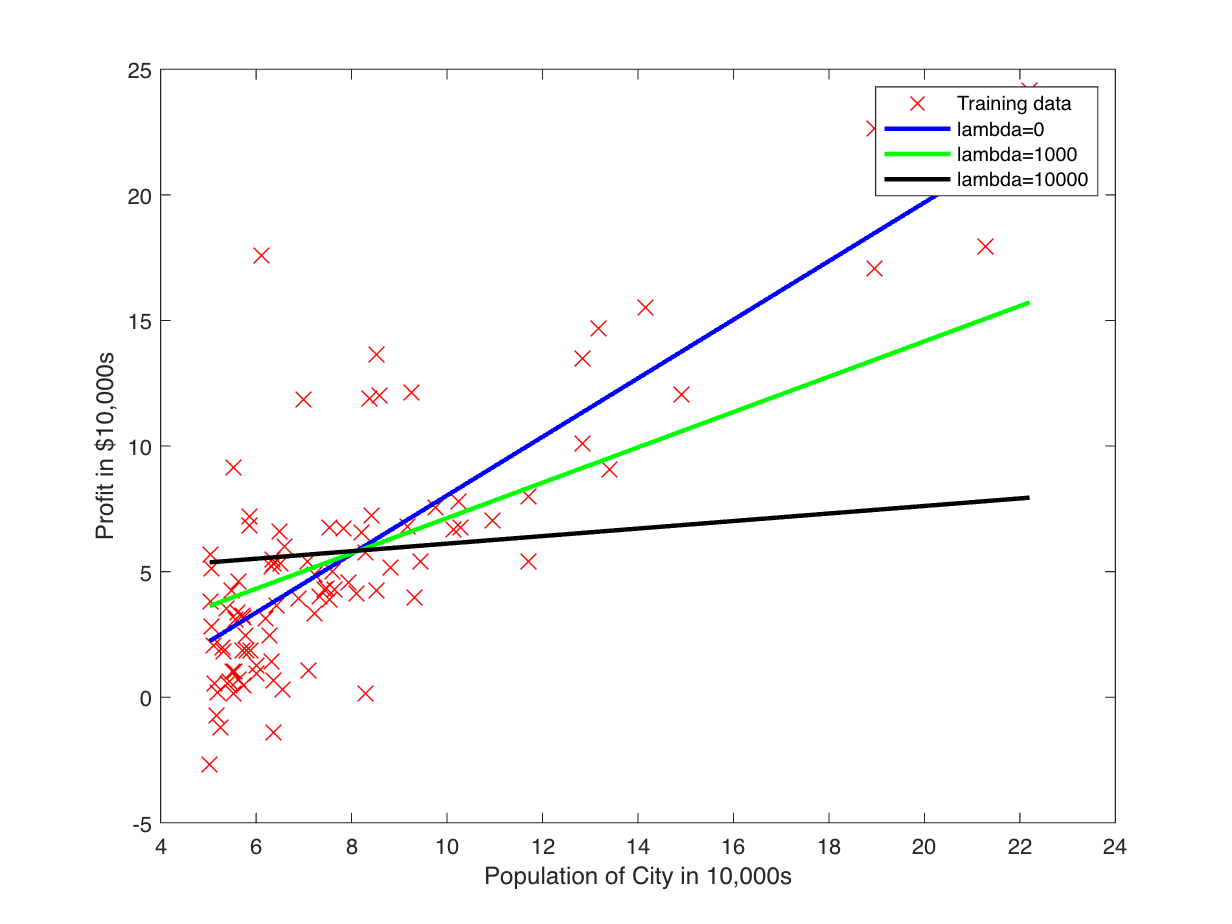

% plot the linear fit
hold on;
plot(X(:,2), X * theta_1, 'b','LineWidth', 2)
plot(X(:,2), X * theta_2, 'g','LineWidth', 2)
plot(X(:,2), X * theta_3, 'k','LineWidth', 2)
legend('Training data', 'lambda=0','lambda=1000','lambda=10000')
hold off

It can be noticed that with lambda equals to 0, we found the same values for theta as in linear regression without regularization. In addition, if lambda is chosen to be too large, it  smooths out the function too much and causes underfitting.

% predict values for population sizes of 35,000 and 70,000 using
% lambda = 10000

predict1 = [1, 3.5] * theta_3;
% previously without regularization we predicted 4519.7678
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);

For population = 35,000, we predict a profit of 51400.786921


predict2 = [1, 7] * theta_3;
% previously without regularization we predicted 45342.4501
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

For population = 70,000, we predict a profit of 56649.940864


## 3. Linear regression with multiple variables

Implementation of linear regression with multiple variables to predict the prices of houses.

The file `data2.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house.

clear
data = load('data2.txt'); % load data
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% print first 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

 x = [2104 3], y = 399900 
 x = [1600 3], y = 329900 
 x = [2400 3], y = 369000 
 x = [1416 2], y = 232000 
 x = [3000 4], y = 539900 
 x = [1985 4], y = 299900 
 x = [1534 3], y = 314900 
 x = [1427 3], y = 198999 
 x = [1380 3], y = 212000 
 x = [1494 3], y = 242500 


### 3.1 Feature normalization

By looking at the values, we note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

% scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);

When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations in order to be able to normalize a new given example before prediction.

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% add intercept term to X
X = [ones(m, 1) X];

### 3.2 Gradient descent

% run gradient descent:

alpha = 0.01; % choose some alpha value
iterations = 1500; % number of iterations

% initialize theta and run gradient descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescent(X, y, theta, alpha, iterations);

% print gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Theta computed from gradient descent:
340412.563014
110540.566546
-6558.990548

% estimate the price of a 1650 sq-ft, 3 br house
predict = [1 (1650 - mu(1)) / sigma(1) (3 - mu(2)) / sigma(2)] * theta; % normalize and then predict
fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', predict);

Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):
 $293101.056857

#### **3.2.1 Selecting learning rates**

iterations = 200; % choose some number of iteration value
theta = zeros(3, 1); % initialize theta
% initialize alpha
alpha_1 = 0.1;
alpha_2 = 0.01;
alpha_3 = 0.001;
% run gradient descent 
[~, J1_history] = gradientDescent(X, y, theta, alpha_1, iterations);
[~, J2_history] = gradientDescent(X, y, theta, alpha_2, iterations);
[~, J3_history] = gradientDescent(X, y, theta, alpha_3, iterations);

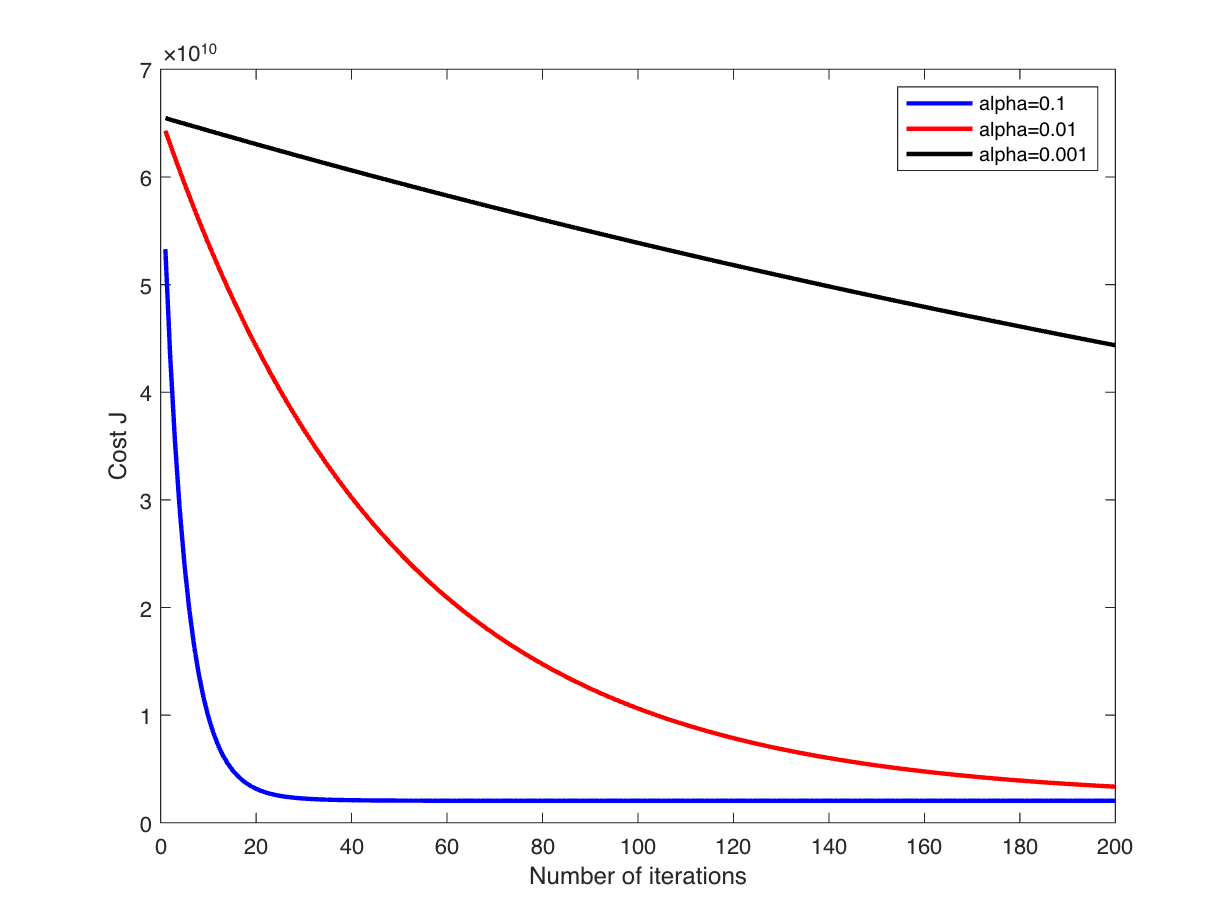

% plot the convergence graph
plot(1:iterations, J1_history, '-b', 'LineWidth', 2);
hold on
plot(1:iterations, J2_history, '-r', 'LineWidth', 2);
plot(1:iterations, J3_history, '-k', 'LineWidth', 2);
legend('alpha=0.1', 'alpha=0.01','alpha=0.001')
hold off
xlabel('Number of iterations');
ylabel('Cost J');

We notice the changes in the convergence curves as the learning rate changes. With a small learning rate, we find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge.

Now with the best learning rate that we found, we run gradient descent until convergence to find the final values of $\theta$.

% run gradient descent :

best_alpha = 1;
iterations = 50;
theta = zeros(3, 1); % initialize theta 
% run gradient descent 
[theta, ~] = gradientDescent(X, y, theta, best_alpha, iterations);

% print gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Theta computed from gradient descent:
340412.659574
110631.050279
-6649.474271

% estimate the price of a 1650 sq-ft, 3 br house
predict = [1 (1650 - mu(1)) / sigma(1) (3 - mu(2)) / sigma(2)] * theta; % normalize and then predict
fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', predict);

Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):
 $293081.464335

By choosing the best learning rate, we could find the best values for theta with much less iterations.

### 3.3 Normal equations

The closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


Using this formula does not require any feature scaling, and we will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

clear
data = load('data2.txt'); % load data
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% add intercept term to X
X = [ones(m, 1) X];

% calculate the parameters from the normal equation
theta = normalEquation(X, y);

% print normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f\n%f', theta(1),theta(2),theta(3));

Theta computed from the normal equations:
89597.909544
139.210674
-8738.019113

Now we use $\theta$ that we found to make a price prediction for a 1650-square-foot house with 3 bedrooms.

% estimate the price of a 1650 sq-ft, 3 br house
predict = [1 1650 3]*theta; 
fprintf('Predicted price of a 1650 sq-ft, 3 br house (using normal equations):\n $%f', predict);

Predicted price of a 1650 sq-ft, 3 br house (using normal equations):
 $293081.464335

We notice that gives the same predicted price as the value we obtained using the model fit with gradient descent.